# Análise de um filtro FIR

clear all;
clc;
close all;


## Função de transferência do filtro

Ts = 1;

N = [1 1 1]*1/3;
D = [1 0 0];

F = tf(N,D,Ts)

F =
 
  0.3333 z^2 + 0.3333 z + 0.3333
  ------------------------------
               z^2
 
Sample time: 1 seconds
Discrete-time transfer function.



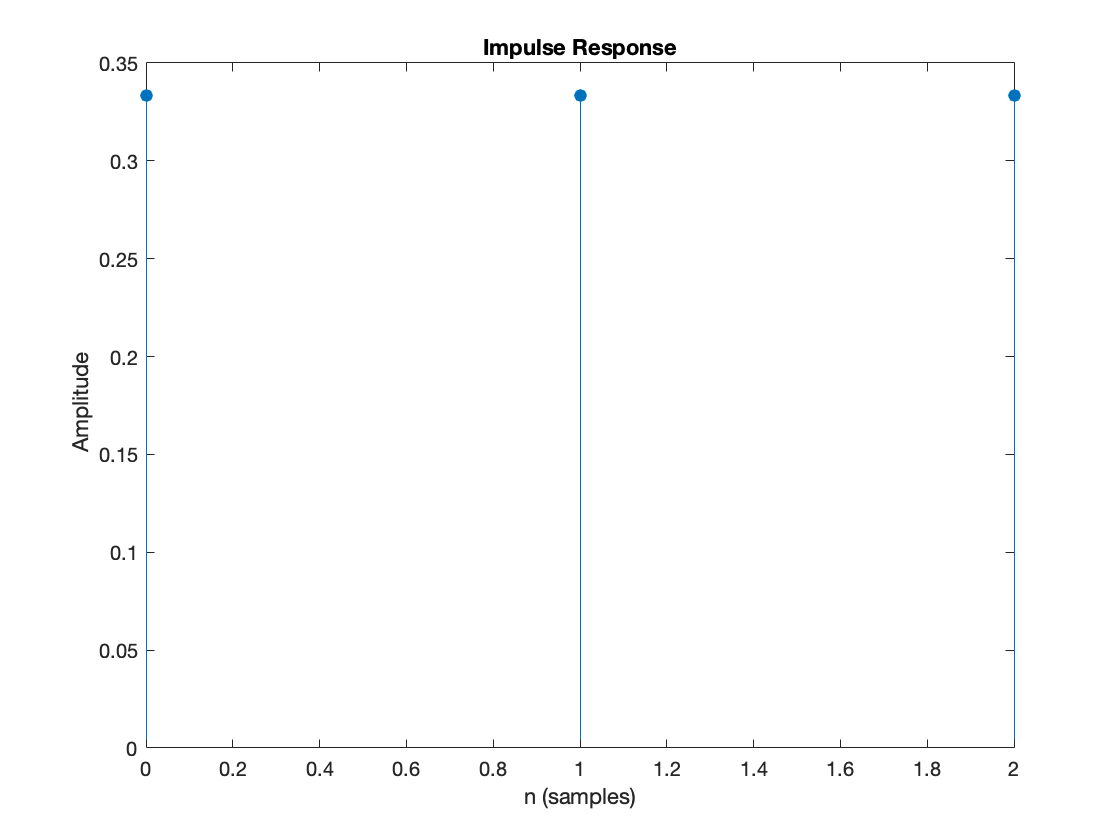

figure()

impz(N,D)   % resposta impulsiva finita

## Determinando os polos e zeros

roots(N)

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i



roots(D)

ans =      0
     0


## Resposta em frequência

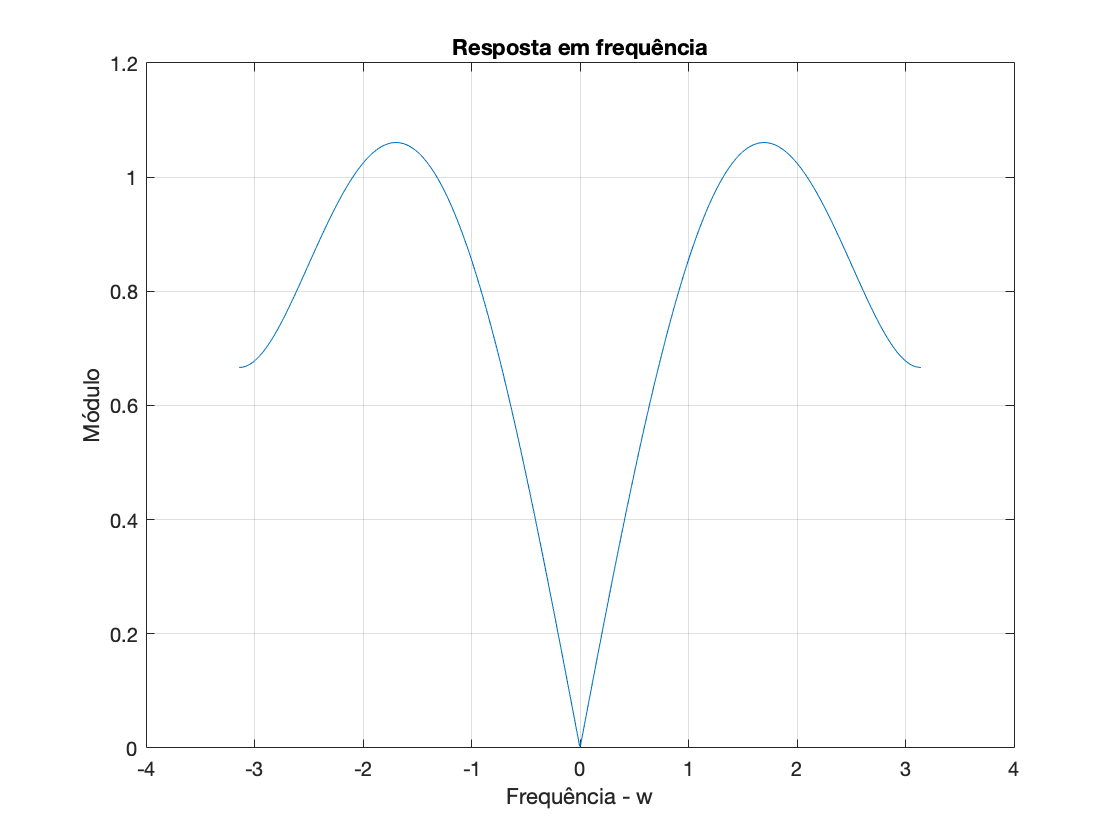


H = @(w,Ts)  1 - 1/3*(1+exp(-j*w*Ts)+exp(-2*j*w*Ts));

ws = (2*pi/Ts);
w = linspace(-ws/2,ws/2,1000);

Hw = H(w,Ts);

plot(w,abs(Hw))
xlabel('Frequência - w');
grid;
ylabel('Módulo')
title('Resposta em frequência')